# Combining Multiple Masks

This file contains the code you saw in the *Combining Multiple Masks* video and is provided for your reference.

Read in the colored chips image:

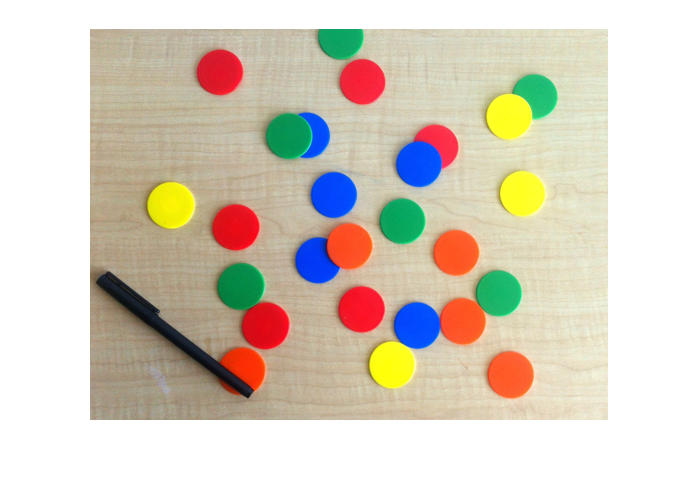

RGB = imread("coloredChips.png"); 
imshow(RGB)

Use the two generated functions (included at the bottom of this script) to find both the bright and dark polarity circles: 

BWdark = segmentChipsDark(RGB); 
BWbright = segmentChipsBright(RGB); 

Combine the masks using a logical OR operator and view the results: 

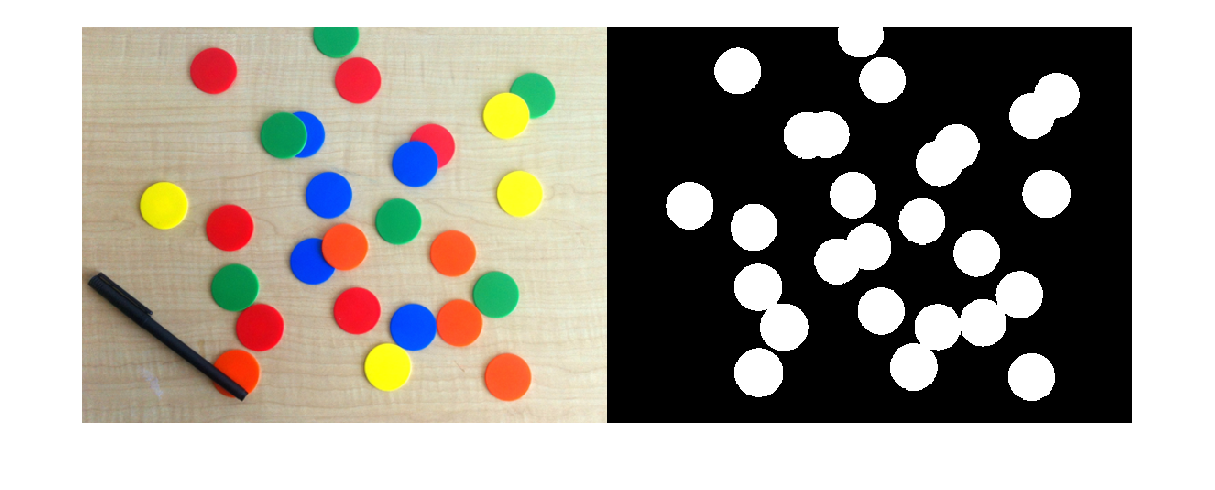

BW = BWdark | BWbright; 
montage({RGB,BW})

Apply the mask to the original image to segment the colored chips: 

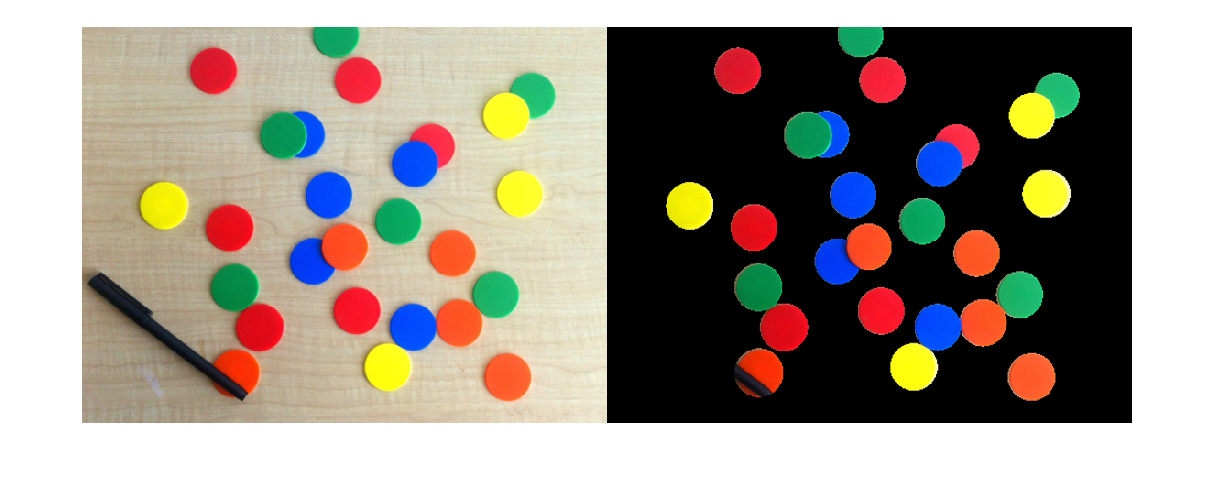

maskedImage = RGB; 
maskedImage(repmat(~BW,1,1,3)) = 0; 
montage({RGB,maskedImage})

## Provided Find Circles Functions

function [BW,maskedImage] = segmentChipsDark(RGB)

% Find circles
[centers,radii,~] = imfindcircles(RGB,[20 75],'ObjectPolarity','dark','Sensitivity',0.88);
BW = false(size(RGB,1),size(RGB,2));
[Xgrid,Ygrid] = meshgrid(1:size(BW,2),1:size(BW,1));
for n = 1:22
    BW = BW | (hypot(Xgrid-centers(n,1),Ygrid-centers(n,2)) <= radii(n));
end

% Create masked image.
maskedImage = RGB;
maskedImage(repmat(~BW,[1 1 3])) = 0;

end

function [BW,maskedImage] = segmentChipsBright(RGB)

% Find circles
[centers,radii,~] = imfindcircles(RGB,[20 75],'ObjectPolarity','bright','Sensitivity',0.88);
BW = false(size(RGB,1),size(RGB,2));
[Xgrid,Ygrid] = meshgrid(1:size(BW,2),1:size(BW,1));
for n = 1:4
    BW = BW | (hypot(Xgrid-centers(n,1),Ygrid-centers(n,2)) <= radii(n));
end

% Create masked image.
maskedImage = RGB;
maskedImage(repmat(~BW,[1 1 3])) = 0;

end

*Copyright 2022 The MathWorks, Inc.*